# [Example 2.2] 

# x(n) = {1,2,3(n = 0),4,5,6,7,6,5,4,3,2,1} 이라고 가정하자.

# 다음 신호들을 구하고 그려라.

#### a. x1(n) = 2x(n-5) - 3x(n+4)

n = -2:10;
x = [1:7, 6:-1:1];

[x11, n11] = sigshift(x,n,5);
[x12, n12] = sigshift(x,n,-4);

[x1, n1] = sigadd(2*x11, n11, -3*x12, n12);

subplot(2,1,1);
stem(n1,x1);
title('Sequence in Example 2.2a');  xlabel('n');    ylabel('x1(n)'); xlim([-7, 16]);

#### b. x2(n) = x(3-n) + x(n)x(n-2)

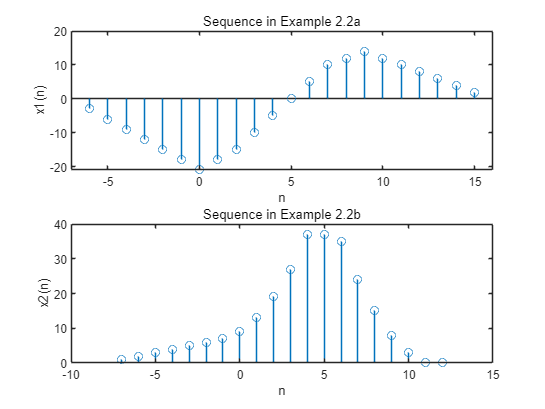

[x21, n21] = sigfold(x,n);
[x21, n21] = sigshift(x21,n21,3);

[x22, n22] = sigshift(x,n,2);
[x22, n22] = sigmult(x,n,x22,n22);

[x2, n2] = sigadd(x21,n21,x22,n22);
subplot(2,1,2);
stem(n2, x2);   title('Sequence in Example 2.2b');  xlabel('n');    ylabel('x2(n)');